Universidad de Costa Rica

Maestría de Computación e Informática

Elaborado por Ruth Campos

Fecha: 18/09/2024

## Aerial Robots

sl_quadrotor
mdl_quadrotor
r = sim("sl_quadrotor");
size(r.result)

ans =         2355          16


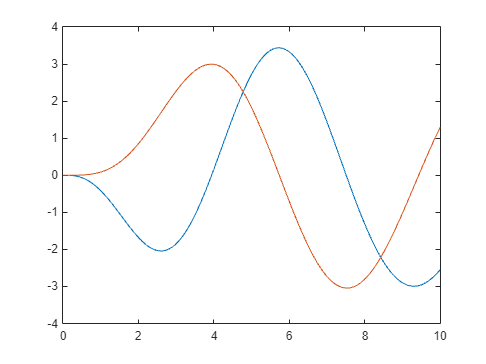

plot(r.t,r.result(:,1:2))

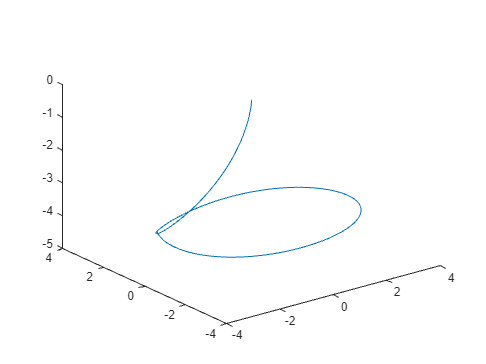

plot3(r.result(:,1),r.result(:,2),r.result(:,3))

### 5.1.1 Braitenberg Vehicles

sl_braitenberg
sim("sl_braitenberg");


### 5.1.2 Simple Automata

load house
whos floorplan

  Name             Size               Bytes  Class     Attributes

  floorplan      397x596            1892896  double              



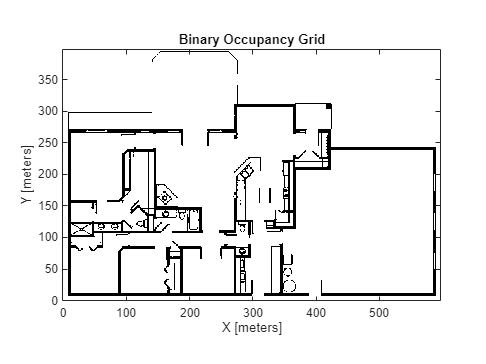

floorMap = binaryOccupancyMap(flipud(floorplan));
figure; floorMap.show

places

places = struct with fields:
     kitchen: [320 190]
      garage: [500 150]
         br1: [50 220]
         br2: [120 50]
         br3: [50 50]
        nook: [320 280]
     mudroom: [320 50]
       patio: [200 350]
       study: [220 50]
      garden: [100 350]
    driveway: [500 350]
      living: [220 200]


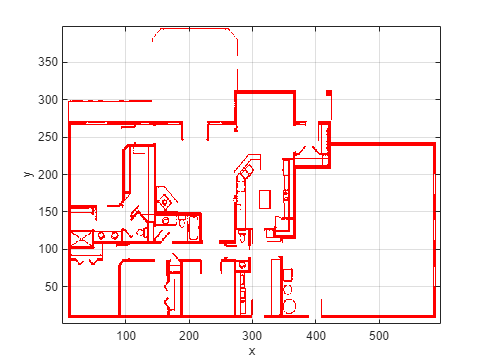

bug = Bug2(floorMap);
bug.plot

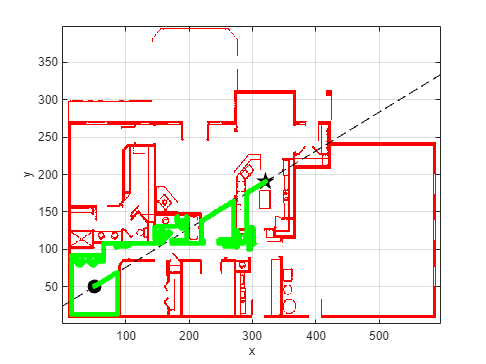

bug.run(places.br3,places.kitchen,animate=true);

p = bug.run(places.br3,places.kitchen);
whos p

  Name         Size            Bytes  Class     Attributes

  p         1300x2             20800  double              




bug.run(places.br3,places.patio,animate=true);
p = bug.run(places.br3,places.kitchen);
whos p
